clear;
fprintf("Sobreamortiguada (E > 1)")

Sobreamortiguada (E > 1)


E=2;       %coeficiente de amortiguamiento
wn=1;       %frecuencia natural no amortiguada

n=[wn^wn];
d=[1 2*E*wn wn^2];

fdt=tf(n,d)


fdt =
 
        1
  -------------
  s^2 + 4 s + 1
 
Continuous-time transfer function.



polos=roots(d)

polos =    -3.7321
   -0.2679


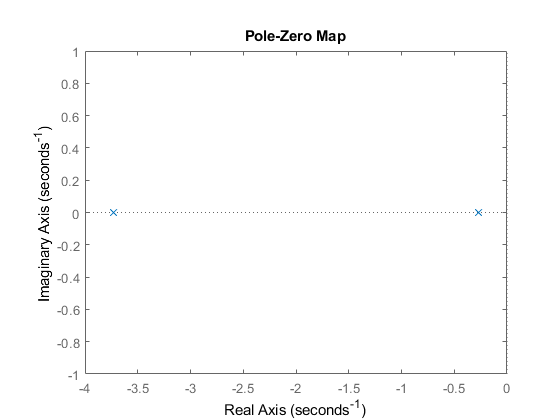

pzmap(fdt)

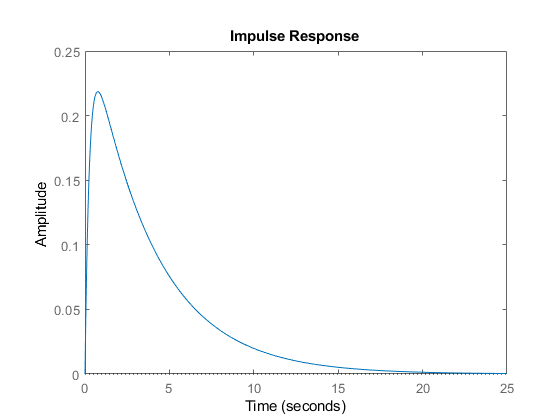

impulse(fdt) 



fprintf("Subamortiguada (0 < E < 1)")

Subamortiguada (0 < E < 1)


E=0.5;       %coeficiente de amortiguamiento
wn=1;       %frecuencia natural no amortiguada

n=[wn^wn];
d=[1 2*E*wn wn^2];

fdt=tf(n,d)


fdt =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



polos=roots(d)

polos =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


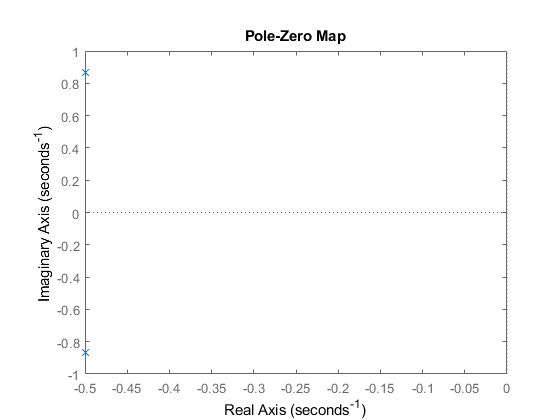

pzmap(fdt)

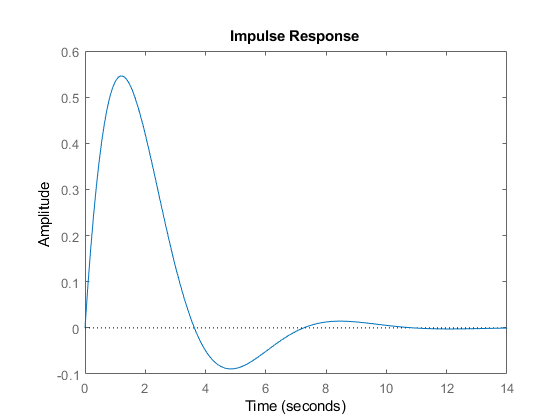

impulse(fdt) 



fprintf("Criticamente amortiguada (E = 1)")

Criticamente amortiguada (E = 1)


E=1;       %coeficiente de amortiguamiento
wn=1;       %frecuencia natural no amortiguada

n=[wn^wn];
d=[1 2*E*wn wn^2];

fdt=tf(n,d)


fdt =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



polos=roots(d)

polos =     -1
    -1


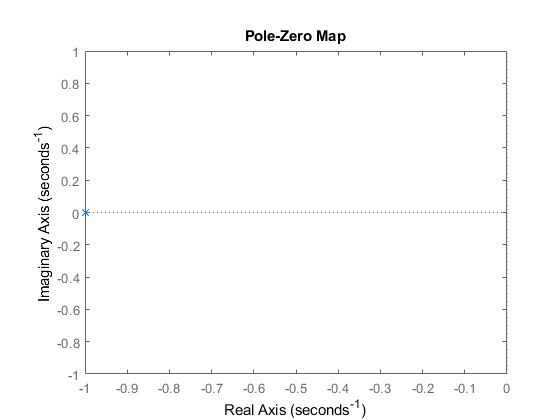

pzmap(fdt)

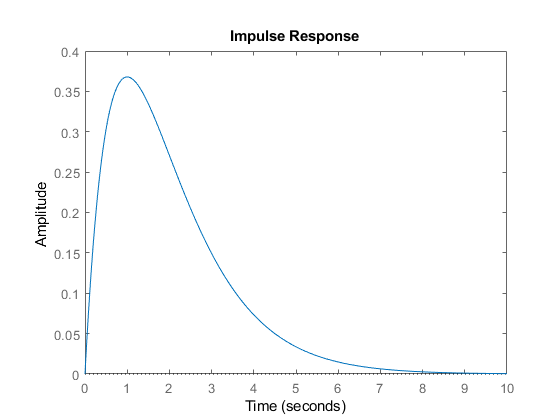

impulse(fdt) 